clear;
clc;
mpc = case33open_new;
V_base = 10;	
lambda_base=mpc.gen(1,6);

P=mpc.bus(:,3);
N=size(P,1);
% path-branch incidence matrix
branch_info=mpc.branch(:,1:2);
P_bus=P(2:N,:);

[H] = gen_path_branch(branch_info,N);
H_modified=H(:,2:N);
R_branch=diag(mpc.branch(:,3));

**With DG**

G_loc=[25,28,31];
G_power=[0.66,0.6,0.67];
switch_1=[25   16   0.1522];
switch_2=[31   13   0.1204];
switch_3=[28   10   0.1330];

P_copy =P;
for i=1:size(G_loc,2)
    loc=G_loc(i);
    power=G_power(i);
   P_copy(loc)= P_copy(loc)-power;
end
P_bus_new=P_copy(2:N,:);
LFP_new=2.*H_modified'*R_branch*H_modified*P_bus_new./V_base.^2;
for i=1:size(G_loc,2)
    loc=G_loc(i)-1;
    disp(LFP_new(loc))
end

    0.0177

    0.0328

    0.0285



disp(LFP_new(1))

    0.0033



LMP_3=(1+[0;LFP_new])*lambda_base;

**Congestion: DG on bus 28, bus 31 increase **

% orgininal without DG
P_ij_ori=H_modified*P_bus;
% with DG
P_bus_new_2=P_bus_new;
% C8, C7
a=0.2;
b=0.25;
P_bus_new_2(27)=P_bus_new(27)-a;
P_bus_new_2(30)=P_bus_new(30)-b;
P_ij_now=H_modified*P_bus_new_2;
display(P_ij_ori(27))

    0.8000



display(P_ij_now(27))

   -0.9200



LFP_new=2.*H_modified'*R_branch*H_modified*P_bus_new_2./V_base.^2;
for i=1:size(G_loc,2)
    loc=G_loc(i)-1;
    disp(LFP_new(loc))
end

    0.0125

    0.0031

   -0.0126



LMP_3=(1+[0;LFP_new])*lambda_base;

G_power(2)=G_power(2)+a;
G_power(3)=G_power(3)+b;
display(G_power(2))

    0.8000



display(G_power(3))

    0.9200



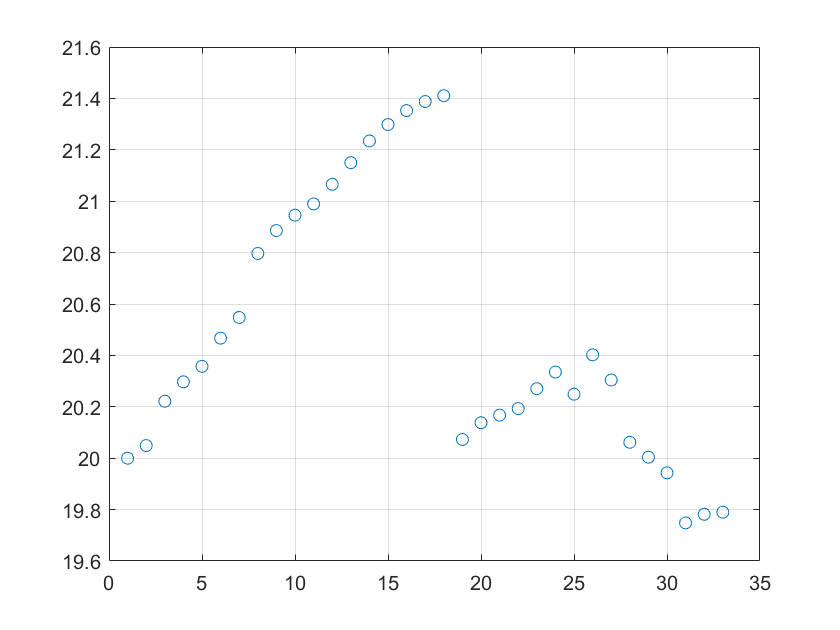

figure
plot(1:N,LMP_3,'o')
grid on

ini_bid=zeros(size(G_loc,2),1);
for i=1:size(G_loc,2)
    loc=G_loc(i);
    ini_bid(i)=LMP_3(loc);
end
disp(ini_bid)

   20.2492
   20.0619
   19.7482



[ini_bid_sort, order]=sort(ini_bid);

**First ETM : bus 31**

% disp(LMP_3(13:18))
H_1=triu(ones(6));
P_1=P(13:18,:);
branch_needed=[switch_2(3),mpc.branch(13,3),mpc.branch(14,3),mpc.branch(15,3),mpc.branch(16,3),mpc.branch(17,3) ];
R_branch_1=diag(branch_needed);
% disp(R_branch_1)
LFP_new=H_1'*R_branch_1*H_1*P_1./V_base.^2;
disp(LMP_3(13:18)./(1+LFP_new))

   21.1386
   21.1783
   21.2082
   21.2336
   21.2500
   21.2606




loss=(H_1*P_1)'*R_branch_1*H_1*P_1./V_base.^2;
P_base=sum(P(13:18));
xx_pre=0:0.005:P_base+loss;
A_lambda_max=ones(1, size(xx_pre,2))*min(LMP_3(13:18)./(1+LFP_new));
mark_x=P_base+loss;
mark_y=min(LMP_3(13:18)./(1+LFP_new));

unit_break=[0];
k=0;
base=18-13;
LMP_ori=LMP_3(13:18);
add_load_unit=0;
incre=0.002;
%A_lambda_max=[];
loss_record=[];
for ii=12:-1:10
    k=k+1;
    loc=ii;
    branch_needed=[branch_needed,mpc.branch(loc,3)];
    R_branch_1=diag(branch_needed);
    P_1=[P_1;P(loc)];
    P_1_loc=P_1;
    H_1=[H_1;zeros(1,k+base)];
    H_1=[H_1 zeros(k+base+1,1)];
    H_1(1,k+base+1)=1;
    for mm=(base+2):(k+base+1)
        H_1(mm,k+base+1)=1;
    end
    %disp(H_1)
    LMP_ori=[LMP_ori;LMP_3(loc)];
    for xx=0:incre:P(loc) 
        P_1_loc(3+k)=xx;
        LFP_new=H_1'*R_branch_1*H_1*P_1_loc./V_base.^2;
%         disp(loc)
%         disp(LFP_new')
%         disp((LMP_ori./(1+LFP_new))')
        A_lambda_max=[A_lambda_max,min(LMP_ori./(1+LFP_new))];
        add_load_unit=add_load_unit+1;
        loss=(H_1*P_1_loc)'*R_branch_1*H_1*P_1_loc./V_base.^2;
        loss_record=[loss_record,loss];
        if xx==0
            mark_x=[mark_x,P_base+(add_load_unit-k)*incre+loss];
            mark_y=[mark_y,min(LMP_ori./(1+LFP_new))];
        end
    end
    mark_x=[mark_x,P_base+(add_load_unit-k)*incre+loss];
    mark_y=[mark_y,min(LMP_ori./(1+LFP_new))];
    unit_break=[unit_break,add_load_unit-k];
end

**plot**

xx=[];
for jj=1:(size(unit_break,2)-1)
    xx=[xx,unit_break(jj):unit_break(jj+1)];
end
xx=P_base+xx*incre+loss_record;
xx_new=[xx_pre,xx];
y_min=ones(1,size(xx_new,2))*ini_bid_sort(1);
loc=G_loc(order(1));
H_self=[1 1; 0 1];
R_self=diag([mpc.branch(31,3),mpc.branch(32,3)]);
P_self=[P(32);P(33)];
loss_self=(H_self*P_self)'*R_self*H_self*P_self./V_base.^2;
surplus_1=G_power(order(1))-P(loc)-P(32)-P(33)-loss_self;
index=find(xx_new>surplus_1,1)-1;
% display(xx_new(index))
% display(surplus_1-xx_new(index))
% final price
final_price_1=(A_lambda_max(index+1)+ini_bid_sort(1))/2;
Final_price_1=round(final_price_1,2);
% BREAK POINT
% corresponding
aaa=1:size(unit_break,2);
aaa=ceil(aaa/2);
unit_break_2=unit_break+aaa+size(xx_pre,2);
real_p_break=xx_new(unit_break_2);
% find how much of 12 is convered by gen 31
break_index=1;
amount=surplus_1-real_p_break(break_index);
display(amount)

amount = 0.0483

mark_loc=A_lambda_max(index+1);



y_end=round(max(mark_y),1)+0.1;
y_begin=round(ini_bid_sort(1),1)-0.1;
y_hor=y_begin:0.1:y_end;
x_hor=ones(1, size(y_hor,2))*surplus_1;

price_str=[num2str(Final_price_1),'\rightarrow'];

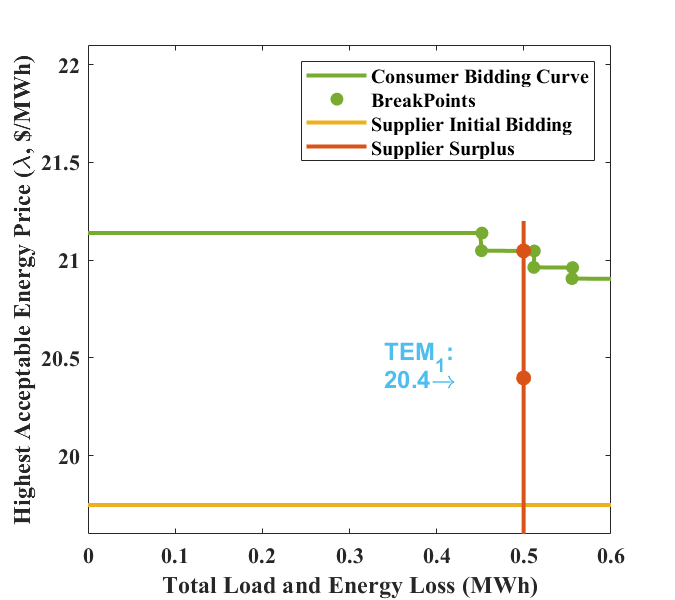


figure
plot(xx_new, A_lambda_max,'LineWidth',2,'Color',[0.4660, 0.6740, 0.1880])
ylim([y_begin,22.1])
xlim([0,0.6])
hold on
plot(mark_x,mark_y,'o', 'markersize', 6,'MarkerFaceColor',[0.4660, 0.6740, 0.1880],'MarkerEdgeColor',[0.4660, 0.6740, 0.1880])
hold on 
plot(xx_new, y_min,'LineWidth',2,'Color',[0.9290, 0.6940, 0.1250])
hold on 
plot(x_hor,y_hor,'LineWidth',2,'Color',[0.8500, 0.3250, 0.0980])
hold on
plot(surplus_1,mark_loc,'o', 'markersize', 7,'MarkerFaceColor',[0.8500, 0.3250, 0.0980],'MarkerEdgeColor',[0.8500, 0.3250, 0.0980])
hold on
plot(surplus_1,final_price_1,'o', 'markersize', 7,'MarkerFaceColor',[0.8500, 0.3250, 0.0980],'MarkerEdgeColor',[0.8500, 0.3250, 0.0980])
hold on
t=text(surplus_1-0.16,final_price_1,price_str);
t(1).Color = [0.3010, 0.7450, 0.9330];
t(1).FontSize = 12;
t(1).FontWeight ='bold';
t=text(surplus_1-0.16,final_price_1+0.11,'TEM_1:');
t(1).Color = [0.3010, 0.7450, 0.9330];
t(1).FontSize = 12;
t(1).FontWeight ='bold';

legend('Consumer Bidding Curve','BreakPoints','Supplier Initial Bidding','Supplier Surplus')
xlabel('Total Load and Energy Loss (MWh)')
ylabel('Highest Acceptable Energy Price (\lambda, $/MWh)')
set(gcf,'Position',[100 100 450 400]);
set(gca,'FontSize',11,'FontName','Times New Roman','FontWeight','Bold')

% figure
% plot(1:add_load_unit,loss_record)
% final price for every one
P_1=[P(16:18,:);P(15);P(14);P(13);amount];
H_1=H_1(1:7,1:7);
branch_needed=branch_needed(1:7);
R_branch_1=diag(branch_needed);
% disp(R_branch_1)
LFP_new=H_1'*R_branch_1*H_1*P_1./V_base.^2;
price_new=(1+LFP_new).*final_price_1;
LMP_ori=[LMP_3(13:18);LMP_3(12)];

display('13,14,15,16,17,18,12')

13,14,15,16,17,18,12


display(LMP_ori')

   21.1500   21.2345   21.2983   21.3526   21.3880   21.4107   21.0658



display(price_new')

   20.4100   20.4531   20.4928   20.5245   20.5461   20.5538   20.4146



display(((LMP_ori-price_new)./LMP_ori*100)')

    3.4990    3.6801    3.7820    3.8784    3.9361    4.0021    3.0912



display( ini_bid_sort(1))

   19.7482



display((final_price_1-ini_bid_sort(1))/ini_bid_sort(1)*100)

    3.2890



**ETM 2: bus 28**

disp(LMP_3(10:12))

   20.9458
   20.9894
   21.0658



H_3=triu(ones(3));
P_3=P(10:12,:);
P_3(3)=P_3(3)-amount;
P_3_record=P_3;
branch_needed=[switch_3(3),mpc.branch(10,3),mpc.branch(11,3) ];
R_branch_3=diag(branch_needed);
% disp(R_branch_3)
LFP_new=H_3'*R_branch_3*H_3*P_3./V_base.^2;
disp(LMP_3(10:12)./(1+LFP_new))

   20.9425
   20.9838
   21.0592




loss=(H_3*P_3)'*R_branch_3*H_3*P_3./V_base.^2;
P_base=sum(P_3);
xx_pre=0:0.005:P_base+loss;
A_lambda_max=ones(1, size(xx_pre,2))*min(LMP_3(10:12)./(1+LFP_new));
mark_x=P_base+loss;
mark_y=min(LMP_3(10:12)./(1+LFP_new));

unit_break=[0];
k=0;
LMP_ori=LMP_3(10:12);
add_load_unit=0;
incre=0.002;
%A_lambda_max=[];
loss_record=[];
for ii=9:-1:7
    k=k+1;
    loc=ii;
    branch_needed=[branch_needed,mpc.branch(loc,3)];
    R_branch_3=diag(branch_needed);
    P_3=[P_3;P(loc)];
    P_3_loc=P_3;
    H_3=[H_3;zeros(1,k+2)];
    H_3=[H_3 zeros(k+3,1)];
    H_3(1,k+3)=1;
    for mm=4:k+3
        H_3(mm,k+3)=1;
    end
%     disp(H_3)
    LMP_ori=[LMP_ori;LMP_3(loc)];
    for xx=0:incre:P(loc) 
        P_3_loc(3+k)=xx;
        LFP_new=H_3'*R_branch_3*H_3*P_3_loc./V_base.^2;
%         disp(loc)
%         disp(LFP_new')
%         disp((LMP_ori./(1+LFP_new))')
        A_lambda_max=[A_lambda_max,min(LMP_ori./(1+LFP_new))];
        add_load_unit=add_load_unit+1;
        loss=(H_3*P_3_loc)'*R_branch_3*H_3*P_3_loc./V_base.^2;
        loss_record=[loss_record,loss];
        if xx==0
            mark_x=[mark_x,P_base+(add_load_unit-k)*incre+loss];
            mark_y=[mark_y,min(LMP_ori./(1+LFP_new))];
        end
    end
    mark_x=[mark_x,P_base+(add_load_unit-k)*incre+loss];
    mark_y=[mark_y,min(LMP_ori./(1+LFP_new))];
    unit_break=[unit_break,add_load_unit-k];
end

**plot**

xx=[];
for jj=1:(size(unit_break,2)-1)
    xx=[xx,unit_break(jj):unit_break(jj+1)];
end
xx=P_base+xx*incre+loss_record;
xx_new=[xx_pre,xx];
y_min=ones(1,size(xx_new,2))*ini_bid_sort(3);
loc=G_loc(order(3));
H_self=[1 1; 0 1];
R_self=diag([mpc.branch(28,3),mpc.branch(29,3)]);
P_self=[P(29);P(30)];
loss_self=(H_self*P_self)'*R_self*H_self*P_self./V_base.^2;
surplus_3=G_power(order(2))-P(28)-P(29)-P(30)-loss_self;
index=find(xx_new>surplus_3,1)-1;
% display(xx_new(index))
% display(surplus_2-xx_new(index))
% final price
final_price_3=(A_lambda_max(index+1)+ini_bid_sort(3))/2;
mark_loc=A_lambda_max(index+1);
Final_price_3=round(final_price_3,2);


% BREAK POINT
% corresponding
aaa=1:size(unit_break,2);
aaa=ceil(aaa/2);
unit_break_2=unit_break+aaa+size(xx_pre,2);
real_p_break=xx_new(unit_break_2);
% find how much of 7 is convered by gen 28
break_index=3;
amount=surplus_3-real_p_break(break_index);
display(amount)

amount = 0.0418



y_end=round(max(mark_y),1)+0.1;
y_begin=round(ini_bid_sort(3),1)-0.1;
y_hor=y_begin:0.1:y_end;
x_hor=ones(1, size(y_hor,2))*surplus_3;

price_str=[num2str(Final_price_3),'\rightarrow'];

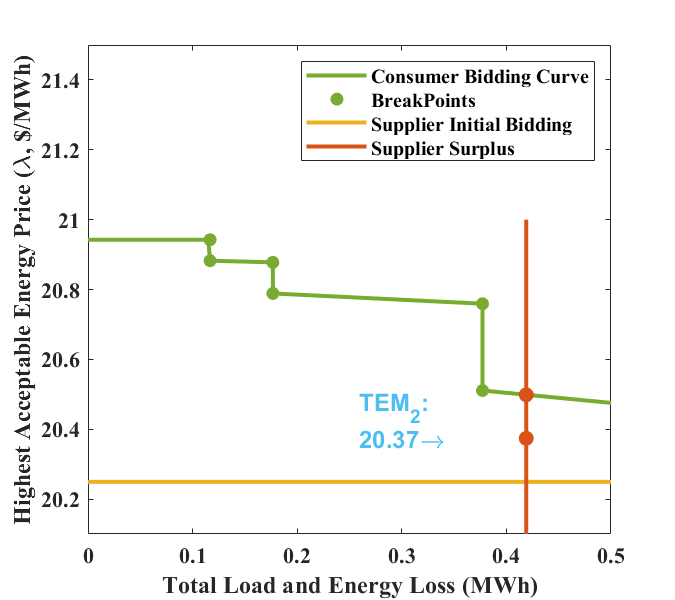


figure
plot(xx_new, A_lambda_max,'LineWidth',2,'Color',[0.4660, 0.6740, 0.1880])
ylim([y_begin, 21.5])
xlim([0, 0.5])
hold on
plot(mark_x,mark_y,'o', 'markersize', 6,'MarkerFaceColor',[0.4660, 0.6740, 0.1880],'MarkerEdgeColor',[0.4660, 0.6740, 0.1880])
hold on 
plot(xx_new, y_min,'LineWidth',2,'Color',[0.9290, 0.6940, 0.1250])
hold on 
plot(x_hor,y_hor,'LineWidth',2,'Color',[0.8500, 0.3250, 0.0980])
hold on
plot(surplus_3,mark_loc,'o', 'markersize', 7,'MarkerFaceColor',[0.8500, 0.3250, 0.0980],'MarkerEdgeColor',[0.8500, 0.3250, 0.0980])
hold on
plot(surplus_3,final_price_3,'o', 'markersize', 7,'MarkerFaceColor',[0.8500, 0.3250, 0.0980],'MarkerEdgeColor',[0.8500, 0.3250, 0.0980])
hold on
t=text(surplus_3-0.16,final_price_3,price_str);
t(1).Color = [0.3010, 0.7450, 0.9330];
t(1).FontSize = 12;
t(1).FontWeight ='bold';
t=text(surplus_3-0.16,final_price_3+0.09,'TEM_2:');
t(1).Color = [0.3010, 0.7450, 0.9330];
t(1).FontSize = 12;
t(1).FontWeight ='bold';

legend('Consumer Bidding Curve','BreakPoints','Supplier Initial Bidding','Supplier Surplus')
xlabel('Total Load and Energy Loss (MWh)')
ylabel('Highest Acceptable Energy Price (\lambda, $/MWh)')
set(gcf,'Position',[100 100 450 400]);
set(gca,'FontSize',11,'FontName','Times New Roman','FontWeight','Bold')

% final price for every one
P_3=[P_3_record;P(9);P(8);amount];
branch_needed=[switch_3(3),mpc.branch(10,3),mpc.branch(11,3),mpc.branch(9,3),mpc.branch(8,3),mpc.branch(7,3) ];
R_branch_3=diag(branch_needed);
% disp(R_branch_2)
LFP_new=H_3'*R_branch_3*H_3*P_3./V_base.^2;
price_new=(1+LFP_new).*final_price_3;
LMP_ori=[LMP_3(10:12);LMP_3(9);LMP_3(8);LMP_3(7)];

display('10,11,12,9,8,7')

10,11,12,9,8,7


display(LMP_ori')

   20.9458   20.9894   21.0658   20.8857   20.7966   20.5476



display(price_new')

   20.3852   20.3875   20.3884   20.4002   20.4165   20.4225



display(((LMP_ori-price_new)./LMP_ori*100)')

    2.6761    2.8676    3.2156    2.3245    1.8279    0.6088



display( ini_bid_sort(2))

   20.0619



display((final_price_3-ini_bid_sort(2))/ini_bid_sort(2)*100)

    1.5551

